# **Introductory script contrasting wavefront-based to Gaussian PSF - based tree shrew optics**

*This script compares the wavefront-based tree shrew optics model to the Gaussian-PSF model*

**See also**: 

- `t_sceneForStimulusOnDisplay.mlx`

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2019*

# **Step 1.** Generate the Gaussian-PSF based TreeShrew optics model

% Default tree shew optics
theDefaultOI = oiTreeShrewCreate('name', 'Gaussian PSF optics');

% Lets see the default values of the treeshrew optics
defaultOpticsParams = opticsTreeShrewDefaultParams()

defaultOpticsParams = struct with fields:
                opticsType: 'gaussian psf'
    inFocusPSFsigmaMicrons: 7
             focalLengthMM: 4.3500
           pupilDiameterMM: 3


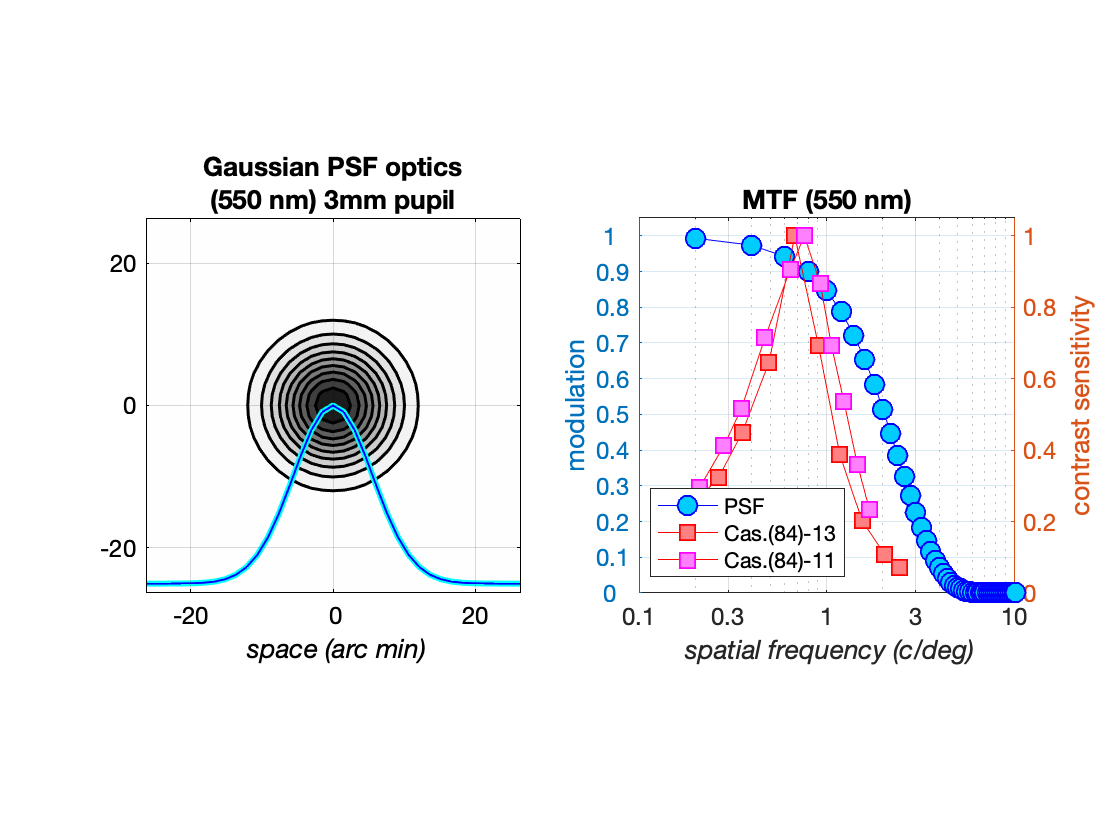


% Visualize the PSF at 550 nm
visualizedSpatialSupportArcMin = 50;
visualizedSpatialSfrequencyCPD = 10.0;
visualizeOptics(theDefaultOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData', csfTreeShrewFromPaper('casagrande84'));

# **Step 2.** Generate the wavefront-aberration based TreeShrew optics model

theWVFOI = oiTreeShrewCreate('opticsType', 'wvf', ...
    'name', 'wvf-based optics');


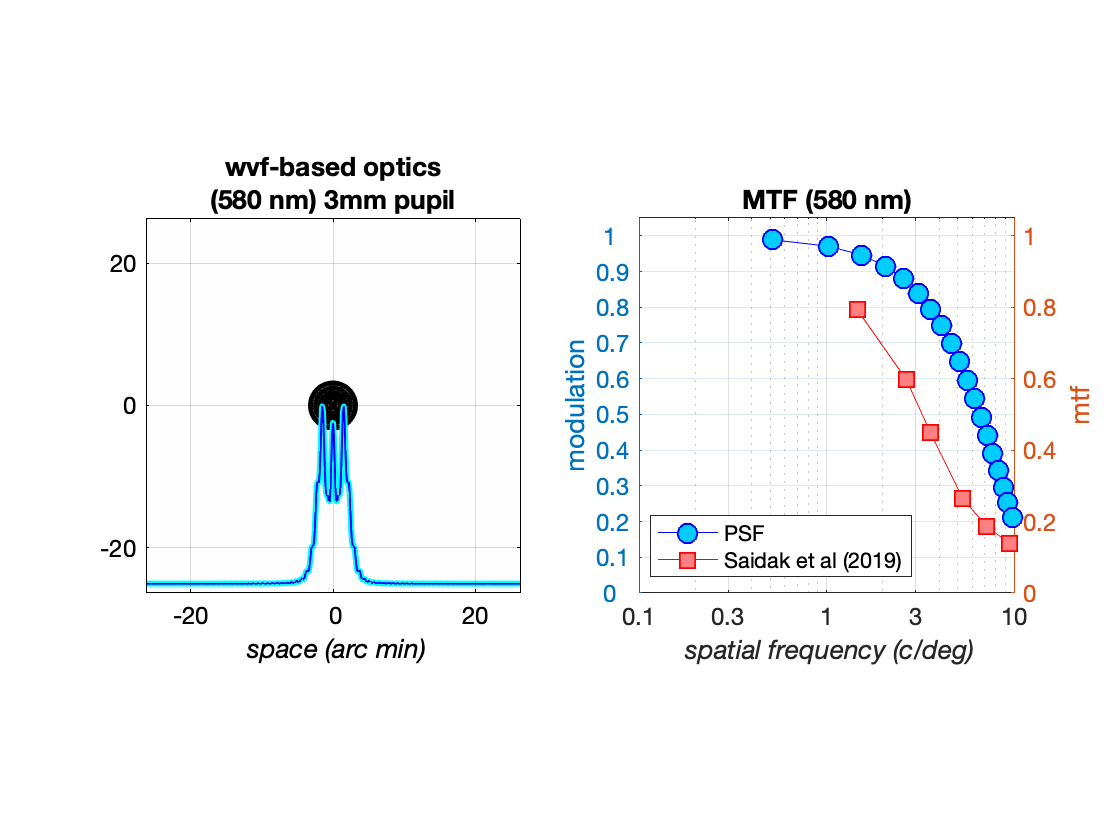

visualizedSpatialSupportArcMin = 50;
visualizedSpatialSfrequencyCPD = 10.0;
visualizeOptics(theWVFOI, 580, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));